# ouverture image

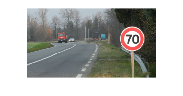


route70 = imread("70route.jpg");
route70 = im2double(route70);
figure(1)
imshow(route70)

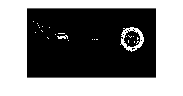


%conversion en hsv
route70hsv = rgb2hsv(route70);
hue = route70hsv(:,:,1);

masque = zeros(size(hue));
masque (hue<0.04 & hue>0) = 1;
masque (hue>0.99& hue<2) = 1;

%SE = strel("diamond",1);

%Masque = imerode(masque,SE);
%Masque = imdilate(Masque,SE);

imshow(masque)